## **Loading in the Data**

The data.mat file has all of the networks (Face-to-Face and Co-Presence).

load('-mat', 'data.mat');

## **Calculate number of edges**

Each network is an adjacency matrix that looks like this:

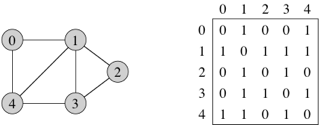

Our first task is to calculate the number of edges in each network. To do this, we add up all of the 1's in the adjacency matrix and divide by 2. The reason we divide by 2 is because each edge is double counted. We use the sum(A, 'all') command on MATLAB to calculate the sum of A where A is a matrix and 'all' to specify the command to add all of the values in the matrix. We can also just calculate the number of 1's in the upper or lower triangle of the matrix.

A_InVS13_SumOfEdges = sum(A_InVS13, 'all')/2;
A_InVS15_SumOfEdges = sum(A_InVS15, 'all')/2;
A_LH10_SumOfEdges = sum(A_LH10, 'all')/2;
A_LyonSchool_SumOfEdges = sum(A_LyonSchool, 'all')/2;
A_pres_InVS13_SumOfEdges = sum(A_pres_InVS13, 'all')/2;
A_pres_InVS15_SumOfEdges = sum(A_pres_InVS15, 'all')/2;
A_pres_LH10_SumOfEdges = sum(A_pres_LH10, 'all')/2;
A_pres_LyonSchool_SumOfEdges = sum(A_pres_LyonSchool, 'all')/2;
A_pres_SFHH_SumOfEdges = sum(A_pres_SFHH, 'all')/2;
A_pres_Thiers13_SumOfEdges = sum(A_pres_Thiers13, 'all')/2;
A_SFHH_SumOfEdges = sum(A_SFHH, 'all')/2;
A_Thiers13_SumOfEdges = sum(A_Thiers13, 'all')/2;

disp(A_InVS13_SumOfEdges);

   755



Above displays the number of edges in the A_InVS13 neptwork.

## **Calculating the Density of each adjacency list**

In order to do this, we must use this equation to calculate the density.


$$\begin{array}{l}
\\
\textrm{density}=\frac{\left(2m\right)}{n\left(n-1\right)}
\end{array}$$


A_InVS13_Density = (2*A_InVS13_SumOfEdges)/(length(A_InVS13)*(length(A_InVS13) - 1));
A_InVS15_Density = (2*A_InVS15_SumOfEdges)/(length(A_InVS15)*(length(A_InVS15) - 1));
A_LH10_Density = (2*A_LH10_SumOfEdges)/(length(A_LH10)*(length(A_LH10) - 1));
A_LyonSchool_Density = (2*A_LyonSchool_SumOfEdges)/(length(A_LyonSchool)*(length(A_LyonSchool) - 1));
A_pres_InVS13_Density = (2*A_pres_InVS13_SumOfEdges)/(length(A_pres_InVS13)*(length(A_pres_InVS13) - 1));
A_pres_InVS15_Density = (2*A_pres_InVS15_SumOfEdges)/(length(A_pres_InVS15)*(length(A_pres_InVS15) - 1));
A_pres_LH10_Density = (2*A_pres_LH10_SumOfEdges)/(length(A_pres_LH10)*(length(A_pres_LH10) - 1));
A_pres_LyonSchool_Density = (2*A_pres_LyonSchool_SumOfEdges)/(length(A_pres_LyonSchool)*(length(A_pres_LyonSchool) - 1));
A_pres_SFHH_Density = (2*A_pres_SFHH_SumOfEdges)/(length(A_pres_SFHH)*(length(A_pres_SFHH) - 1));
A_pres_Thiers13_Density = (2*A_pres_Thiers13_SumOfEdges)/(length(A_pres_Thiers13)*(length(A_pres_Thiers13) - 1));
A_SFHH_Density = (2*A_SFHH_SumOfEdges)/(length(A_SFHH)*(length(A_SFHH) - 1));
A_Thiers13_Density = (2*A_Thiers13_SumOfEdges)/(length(A_Thiers13)*(length(A_Thiers13) - 1));

## **Calculating Degree Distribution**

In order to calculate the degree distribution for each node/vertex in a vertex we must add up all of the 1's in each row. To do this we create a new variable and assign that variable to the sum of all 1's in each column in the database provided in the sum function.

A_InVS13_DegreeDistribution = sum(A_InVS13, 1);
A_InVS15_DegreeDistribution = sum(A_InVS15, 1);
A_LH10_DegreeDistribution = sum(A_LH10, 1);
A_LyonSchool_DegreeDistribution = sum(A_LyonSchool, 1);
A_pres_InVS13_DegreeDistribution = sum(A_pres_InVS13, 1);
A_pres_InVS15_DegreeDistribution = sum(A_pres_InVS15, 1);
A_pres_LH10_DegreeDistribution = sum(A_pres_LH10, 1);
A_pres_LyonSchool_DegreeDistribution = sum(A_pres_LyonSchool, 1);
A_pres_SFHH_DegreeDistribution = sum(A_pres_SFHH, 1);
A_pres_Thiers13_DegreeDistribution = sum(A_pres_Thiers13, 1);
A_SFHH_DegreeDistribution = sum(A_SFHH, 1);
A_Thiers13_DegreeDistribution = sum(A_Thiers13, 1);

## **Plotting Degree Distribution**

In order to compare the Face-to-Face networks and the Co-Presence networks we need to run histogram commands to visualize the data.

A_InVS13_DegreeDistributionHistogram = histogram(A_InVS13_DegreeDistribution);

A_InVS15_DegreeDistributionHistogram = histogram(A_InVS15_DegreeDistribution);

A_LH10_DegreeDistributionHistogram = histogram(A_LH10_DegreeDistribution);

A_LyonSchool_DegreeDistributionHistogram = histogram(A_LyonSchool_DegreeDistribution);

A_pres_InVS13_DegreeDistributionHistogram = histogram(A_pres_InVS13_DegreeDistribution);

A_pres_InVS15_DegreeDistributionHistogram = histogram(A_pres_InVS15_DegreeDistribution);

A_pres_LH10_DegreeDistributionHistogram = histogram(A_pres_LH10_DegreeDistribution);

A_pres_LyonSchool_DegreeDistributionHistogram = histogram(A_pres_LyonSchool_DegreeDistribution);

A_pres_SFHH_DegreeDistributionHistogram = histogram(A_pres_SFHH_DegreeDistribution);

A_pres_Thiers13_DegreeDistributionHistogram = histogram(A_pres_Thiers13_DegreeDistribution);

A_SFHH_DegreeDistributionHistogram = histogram(A_SFHH_DegreeDistribution);

A_Thiers13_DegreeDistributionHistogram = histogram(A_Thiers13_DegreeDistribution);

## **Calculating the Clustering Coefficient**

In order to calculate the clustering coefficient we need to multiply 2 by the cube of the database for that vertex/node (the number of paths of length 3 for that vertex/node). Then we have to divide this value by the degree of the vertex/node and the degree of the vertex/node minus 1.


$$\textrm{cc}\left(v\right)=\frac{\left(2|\Delta v|\right)}{\deg \left(v\right)\left(\deg \left(v\right)-1\right)}$$


A_InVS13_ClusteringCoefficient = rdivide(2 * transpose(diag(A_InVS13^3)), times(A_InVS13_DegreeDistribution, A_InVS13_DegreeDistribution - 1));
A_InVS15_ClusteringCoefficient = rdivide(2 * transpose(diag(A_InVS15^3)), times(A_InVS15_DegreeDistribution, A_InVS15_DegreeDistribution - 1));
A_LH10_ClusteringCoefficient = rdivide(2 * transpose(diag(A_LH10^3)), times(A_LH10_DegreeDistribution, A_LH10_DegreeDistribution - 1));
A_LyonSchool_ClusteringCoefficient = rdivide(2 * transpose(diag(A_LyonSchool^3)), times(A_LyonSchool_DegreeDistribution, A_LyonSchool_DegreeDistribution - 1));
A_pres_InVS13_ClusteringCoefficient = rdivide(2 * transpose(diag(A_pres_InVS13^3)), times(A_pres_InVS13_DegreeDistribution, A_pres_InVS13_DegreeDistribution - 1));
A_pres_InVS15_ClusteringCoefficient = rdivide(2 * transpose(diag(A_pres_InVS15^3)), times(A_pres_InVS15_DegreeDistribution, A_pres_InVS15_DegreeDistribution - 1));
A_pres_LH10_ClusteringCoefficient = rdivide(2 * transpose(diag(A_pres_LH10^3)), times(A_pres_LH10_DegreeDistribution, A_pres_LH10_DegreeDistribution - 1));
A_pres_LyonSchool_ClusteringCoefficient = rdivide(2 * transpose(diag(A_pres_LyonSchool^3)), times(A_pres_LyonSchool_DegreeDistribution, A_pres_LyonSchool_DegreeDistribution - 1));
A_pres_SFHH_ClusteringCoefficient = rdivide(2 * transpose(diag(A_pres_SFHH^3)), times(A_pres_SFHH_DegreeDistribution, A_pres_SFHH_DegreeDistribution - 1));
A_pres_Thiers13_ClusteringCoefficient = rdivide(2 * transpose(diag(A_pres_Thiers13^3)), times(A_pres_Thiers13_DegreeDistribution, A_pres_Thiers13_DegreeDistribution - 1));
A_SFHH_ClusteringCoefficient = rdivide(2 * transpose(diag(A_SFHH^3)), times(A_SFHH_DegreeDistribution, A_SFHH_DegreeDistribution - 1));
A_Thiers13_ClusteringCoefficient = rdivide(2 * transpose(diag(A_Thiers13^3)), times(A_Thiers13_DegreeDistribution, A_Thiers13_DegreeDistribution - 1));